# RunTest Example for Neural Hybrid System Learning Toolbox Design

clear
close all
clc


## Initialization

SystemOrder=1;
Maximum_Dimension=2;
SystemStateDimension=2;
tol = 0.2;
maximum_entropy=60;
NeuronNum_swith=10;
NeuronNum_single=100;
TF='ReLu';
timetic=3;
e=1.5e-5; % Expected Merged Tolerence
VerificationNum=40;
VerificationDuration=1000;
TrainingStateDimension=1;

VerificationU_input=[];
% Abstraction
AbstractionNum=100;
AbstractionDuration=400;
% Decrease Self Loop Num
SelfLoopNum=100;

folderPath = fullfile('Results', 'fig');
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

** 1. Load Data**



files = dir('DataSet/LASA Data Set/*');
names = {};
for k = 1:length(files)
    if ~files(k).isdir
        [~, name, ~] = fileparts(files(k).name);
        names{end+1} = name;
    end
end
for RecordTimes=1:30
load(['DataSet/LASA Data Set/' names{RecordTimes}],'demos','dt')
for i = 1:size(demos,2)
    TrajData{i} = demos{i}.pos;
    plot(TrajData{i}(1,:),TrajData{i}(2,:))
    hold on
end
minvalue=zeros(size(TrajData{1},1),1);
maxvalue=minvalue;
minvalue=minvalue+100;
for i = 1:size(demos,2)
    TrajData{i} = demos{i}.pos;
    tempmin=TrajData{i}(:,1);
    tempmax=TrajData{i}(:,1);
    maxvalue=max([tempmax';maxvalue'])';
    minvalue=min([tempmin';minvalue'])';
end
InitialBound=[minvalue-1.5,maxvalue+1.5];

%1.1 Trajectories to Samples

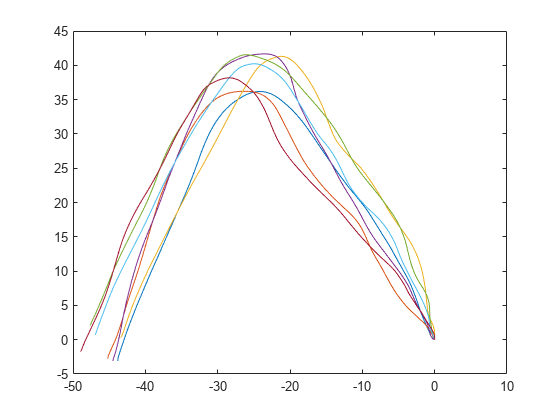

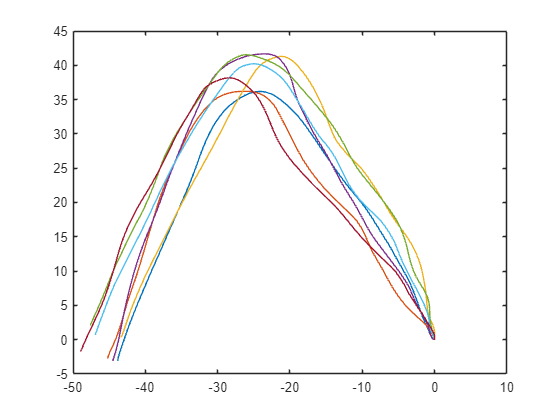


% xs is the traing set of state \times system orders
TrajNum=size(TrajData,2);
xs=zeros((size(TrajData{1},2)-SystemOrder)*TrajNum,SystemStateDimension*SystemOrder);
t=zeros((size(TrajData{1},2)-SystemOrder)*TrajNum,SystemStateDimension);
for i = 1:TrajNum
    Begin=(size(TrajData{1},2)-1)*(i-1)+1;
    End = (size(TrajData{1},2)-1)*(i-1)+size(TrajData{1},2);    
    for k= 1:SystemStateDimension
            t(Begin:End-SystemOrder,k) = TrajData{i}(k,SystemOrder+1:end);
        for j = 1:SystemOrder
            xs(Begin:End-SystemOrder,SystemStateDimension*(j-1)+k) = TrajData{i}(k,j:end-SystemOrder+j-1);            
        end
    end
end

if (size(TrajData{1},1)~=SystemStateDimension)
    for i=1:TrajNum
        externalinput=TrajData{i}(SystemStateDimension+1:end,:)';
        xs=[xs externalinput];
    end
end


**2. Mapminmax**

[xsn, ps_input] = mapminmax(xs',-1,1);
ps_output.name = ps_input.name;
ps_output.xrows=SystemStateDimension;
ps_output.yrows=SystemStateDimension;
ps_output.xmax=ps_input.xmax(1:SystemStateDimension,:);
ps_output.xmin=ps_input.xmin(1:SystemStateDimension,:);
ps_output.xrange=ps_input.xrange(1:SystemStateDimension,:);
ps_output.ymax=1;
ps_output.ymin=-1;
ps_output.yrange=2;
ps_output.gain=ps_input.gain(1:SystemStateDimension);
ps_output.xoffset=ps_input.xoffset(1:SystemStateDimension);
ps_output.no_change=0;
[tn] = mapminmax('apply',t',ps_output);
Numsamples=size(xs,1);


** 3.Samples without input**

xsnu=xsn(1:SystemOrder*SystemStateDimension,:);


## Neural Hybrid System Learning 

**%1.Principle Compoent Analysis**

maximum_entropy=200; 
idx=Maximum_Dimension;% Dimensional-wise Select
    mu=zeros(1,Maximum_Dimension);
    coeff=eye(Maximum_Dimension);
    utest = (xsnu'-mu)*coeff(:,1:idx);
    bounderies = zeros(idx,2);
    for i= 1:idx
        bounderies(i,1)=min(utest(:,i))-0.2;
        bounderies(i,2)=max(utest(:,i))+0.2;
    end
    lowerbound=bounderies(:,1);
    upperbound= bounderies(:,2);
    init_interval{1}=bounderies;


** 2.Data-driven Partitioning (using mapminmax samples)**

    P=partitions(init_interval,xsnu',tn');
    intervals=ME(P,tol,maximum_entropy,Maximum_Dimension,mu',coeff(:,1:idx)');

Starting Maximum Entropy Partitioning with epsilon=200
Number of Partitions 1
Elapsed time is 0.020393 seconds.
Number of Partitions 2
Elapsed time is 0.020796 seconds.
Number of Partitions 3
Elapsed time is 0.011068 seconds.
Number of Partitions 4
Elapsed time is 0.008280 seconds.
Number of Partitions 4
Elapsed time is 0.008228 seconds.
Number of Partitions 4
Elapsed time is 0.008322 seconds.
Number of Partitions 4
Elapsed time is 0.008269 seconds.
Number of Partitions 4
Elapsed time is 0.013032 seconds.
Number of Partitions 5
Elapsed time is 0.010912 seconds.
Number of Partitions 6
Elapsed time is 0.011344 seconds.
Number of Partitions 7
Elapsed time is 0.009415 seconds.
Number of Partitions 8
Elapsed time is 0.009343 seconds.
Number of Partitions 9
Elapsed time is 0.008512 seconds.
Number of Partitions 9
Elapsed time is 0.008113 seconds.
Number of Partitions 9
Elapsed time is 0.011228 seconds.
Number of Partitions 10
Elapsed time is 0.010875 seconds.
Number of Partitions 11
Elapsed 

    %intervals=ME(P,tol,maximum_entropy,Dimension,mu',coeff(:,1:idx)');
    P.intervals=intervals;
    P.input=xsn';


**3.Initialized ELM and Merge Partitions**

    tic
    ELMs1=ELM.GenerateELM(size(xs,2),NeuronNum_swith,TF,size(t,2)); 
    [P1,ELMs]=MergePatitions(P,ELMs1,e,mu',coeff(:,1:idx)',size(xsnu,1));

Starting Merging redundant partitions, there are 47partitionstime of training ELM is 4.555000e-04 seconds 
time of training ELM is 5.240000e-04 seconds 
time of training ELM is 4.247000e-04 seconds 
time of training ELM is 3.546000e-04 seconds 
time of training ELM is 3.848000e-04 seconds 
time of training ELM is 2.911000e-04 seconds 
time of training ELM is 4.336000e-04 seconds 
time of training ELM is 5.341000e-04 seconds 
time of training ELM is 3.576000e-04 seconds 
time of training ELM is 5.506000e-04 seconds 
time of training ELM is 5.109000e-04 seconds 
time of training ELM is 6.027000e-04 seconds 
time of training ELM is 5.075000e-04 seconds 
time of training ELM is 7.887000e-04 seconds 
time of training ELM is 6.770000e-04 seconds 
time of training ELM is 7.836000e-04 seconds 
time of training ELM is 7.368000e-04 seconds 
time of training ELM is 1.133700e-03 seconds 
time of training ELM is 9.856000e-04 seconds 
time of training ELM is 9.697000e-04 seconds 
time of training EL

 clc
 TrainingTimeforParallelSwitch(RecordTimes)=max(SwitchTrainingTime);
 clear SwitchTrainingTime
    size(P.intervals,2)

ans = 47

    size(P1.intervals,2)

ans = 1

    mse_switch = 0;
    min_mse_switch=1;
    for i = 1:size(ELMs,2)
        if (mse_switch<ELMs(i).trainingError)
                mse_switch = ELMs(i).trainingError;
        end
        if (min_mse_switch>ELMs(i).trainingError)
                min_mse_switch = ELMs(i).trainingError;
        end
    end
    MSEforParallelSwitch(RecordTimes)=mse_switch;
    %fprintf('the maximum training error using the normalized model is'); 
    disp(mse_switch); 

   1.9415e-06



toc

Elapsed time is 0.002381 seconds.


**4.Train a Complex Neural Network Model as referance**

    ELMs1=ELM.GenerateELM(size(xs,2),NeuronNum_single,TF,size(t,2));
    tic
    ELMs1=trainELM(ELMs1,xsn,tn);

time of training ELM is 1.685610e-02 seconds 


    TrainingTimeforELM(RecordTimes)=toc;
    MSEforELM(RecordTimes)=ELMs1.trainingError;

 **5.Plot traces and partitions (on feature space) **

% 5.1 Partitions and Merged Partitions Ploting 

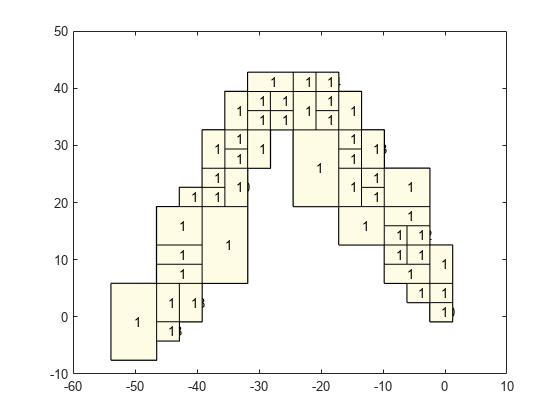

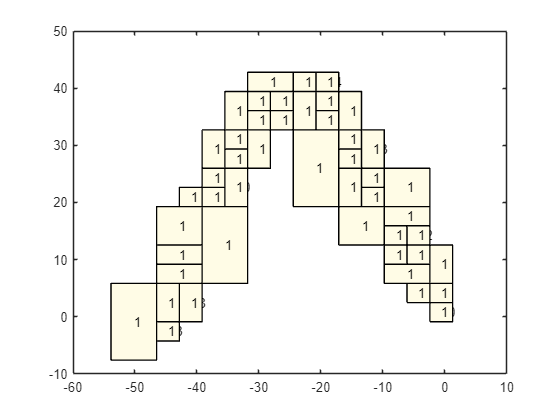

    tic
    NonsinglePartionCounter=0;
    for i=1:size(P1.intervals,2)
        if(size(P1.intervals{i},1)~=Maximum_Dimension)
            NonsinglePartionCounter=NonsinglePartionCounter+1;
        end
    end
    for i = 1: size(P.intervals,2)
        for j = 0:Maximum_Dimension:size(P.intervals{i},1)-1
            for z=1:2
               reverseminmaxP{i}(j+1:j+Maximum_Dimension,z)=mapminmax('reverse',P.intervals{i}(j+1:j+Maximum_Dimension,z),ps_output);
            end
        end
    end
    for i = 1: size(P1.intervals,2)
        for j = 0:Maximum_Dimension:size(P1.intervals{i},1)-1
            for z=1:2
               reverseminmaxP1{i}(j+1:j+Maximum_Dimension,z)=mapminmax('reverse',P1.intervals{i}(j+1:j+Maximum_Dimension,z),ps_output);
            end
        end
    end


MergePartitionFig=figure;
        partitions.intervalplot(reverseminmaxP,'empty','black')
    hold on
        partitions.MergeIntervalPlot(reverseminmaxP1,Maximum_Dimension,NonsinglePartionCounter)  
figPath = fullfile('Results/fig', strcat(num2str(RecordTimes),'.',names{RecordTimes},'_Merge.fig'));
pngPath = fullfile('Results/png', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_Merge.png')));
epsPath = fullfile('Results/eps', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_Merge.eps')));
saveas(MergePartitionFig, figPath);
saveas(MergePartitionFig, pngPath);

saveas(MergePartitionFig, epsPath);
clear figPath pngPath epsPath reverseminmaxP1

% 5.2 Random Trace Ploting

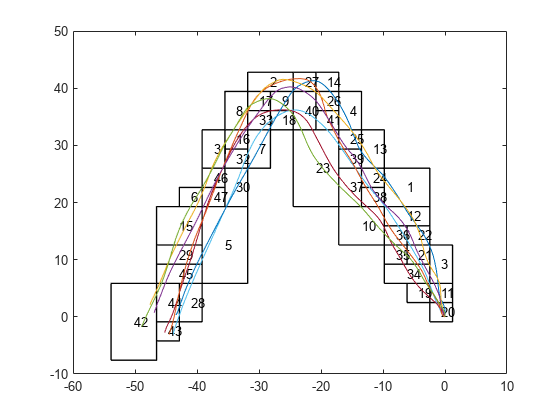

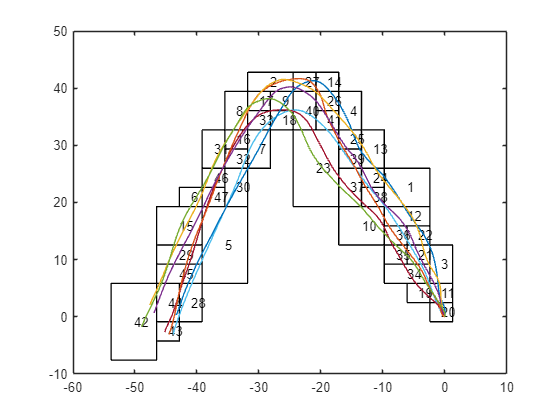

 
SamplesPartitionsFig=figure;
        partitions.intervalplot(reverseminmaxP,'empty','black')
        hold on 

for i = 1:size(demos,2)
    TrajData{i} = demos{i}.pos;
    plot(TrajData{i}(1,:),TrajData{i}(2,:))
    hold on
end

figPath = fullfile('Results/fig', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_SamplesPartitionsFig.fig')));
pngPath = fullfile('Results/png', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_SamplesPartitionsFig.png')));
epsPath = fullfile('Results/eps', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_SamplesPartitionsFig.eps')));
saveas(SamplesPartitionsFig, figPath);
saveas(SamplesPartitionsFig, pngPath);

saveas(SamplesPartitionsFig, epsPath);
clear figPath pngPath epsPath reverseminmaxP
      %(PCA featuring and phase ploting Prediction Mode & Simulation Mode (Randomlized external Input))

% 5.2.1 Prediction Mode 

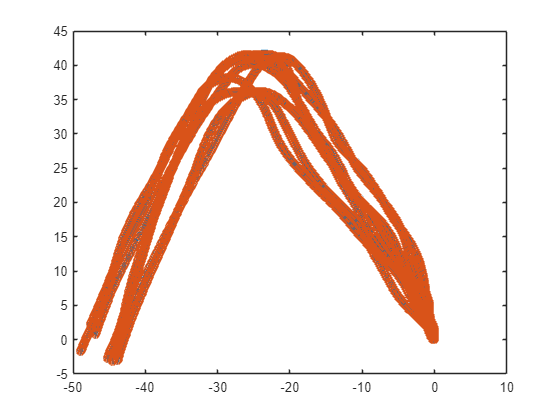

                    segmentIndex=P1.intervals;
                    inputspace1=P1.intervals;
                    for i = 1:size(tn,2)
                            for k = 1:size(segmentIndex,2)
                                      if(partitions.ifin(coeff(:,1:idx)'*(xsnu(:,i)-mu'),segmentIndex{k},Maximum_Dimension)==1)
                                               output_switch(:,i)= ELMpredict(ELMs(k),xsn(:,i));
                                      end
                            end
                    end
                    ON_S= mapminmax('reverse',output_switch(:,1:end),ps_output); 
                    if (size(tn,1)==2)
                        figure
                        plot(t(:,1)',t(:,2)','*')
                        hold on 
                        plot(ON_S(1,:),ON_S(2,:),'o')             
                    end 

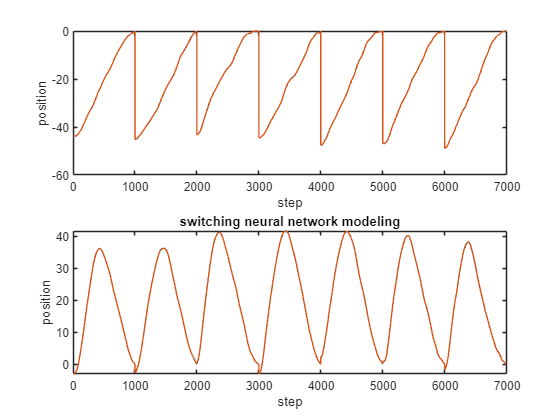

                    figure
                    for i = 1:size(t',1)
                            subplot(size(t',1),1,i)
                            plot(1:size(t',2),t(:,i))
                            hold on 
                            plot(1:size(t',2),ON_S(i,:))
                            xlabel('step')
                            ylabel('position')
                            hold on
                    end

                    title('switching neural network modeling')

% 5.2.2 Simulation Mode

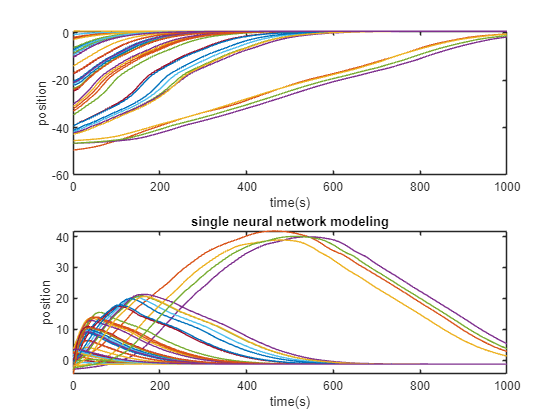

           BoundInterval=InitialBound;
            for i = 2:SystemOrder
                BoundInterval=[BoundInterval;InitialBound'];
            end
            RandomStateInput = intervalCompute.randomPoint(BoundInterval,VerificationNum);
            RandomStateInput = mapminmax('apply', RandomStateInput,ps_input); 
            for j =1:VerificationNum  
                        for l =1:SystemOrder
                            Traj_single{j}(:,l)=RandomStateInput((l-1)*SystemStateDimension+1:l*SystemStateDimension,j);
                        end
                     Traj_switch{j}=Traj_single{j};
                    flag=0;
                for i =SystemOrder+1:VerificationDuration
                    for l = 1:SystemOrder
                      if(size(Traj_switch{j},2)==i-1)
                        Traj_switchinput((l-1)*SystemOrder+1:l*SystemStateDimension,:)=Traj_switch{j}(:,i-l);
                        flag=1;
                      else
                        flag=0;
                      end
                        Traj_singleinput((l-1)*SystemOrder+1:l*SystemStateDimension,:)=Traj_single{j}(:,i-l);                   
                    end
                    
                    if(flag)
                        %InputNs=mapminmax('apply',[Traj_switchinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)],ps_input);
                        InputNs=[Traj_switchinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)];
                    end
                    %InputN=mapminmax('apply',[Traj_singleinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)],ps_input);
                    InputN=[Traj_singleinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)];
                    %  tic

                    if (size(xsn,1)-SystemStateDimension*SystemOrder)
                        u_input=-1 + 2*rand(size(xsn,1)-SystemStateDimension*SystemOrder,1);
                        InputNs= [InputNs(1:SystemOrder*SystemStateDimension);u_input];
                        Traj_singleN=ELMpredict(ELMs1,[InputN(1:SystemOrder*SystemStateDimension);u_input]);                       
                    else 
                        InputNs= [InputNs(1:SystemOrder*SystemStateDimension)];
                        Traj_singleN=ELMpredict(ELMs1,InputN);
                    end
                    
                   % Traj_single{j}(:,i)=mapminmax('reverse',Traj_singleN,ps_output);
                   Traj_single{j}(:,i)=Traj_singleN;
                    if(flag)
                        for k = 1:size(segmentIndex,2)
                              if(partitions.ifin(coeff(:,1:idx)'*(InputNs(1:SystemOrder*SystemStateDimension,:)-mu'),segmentIndex{k},Maximum_Dimension)==1)
                                       Traj_switchN= ELMpredict(ELMs(k),InputNs);
                                       Traj_switch{j}(:,i)=(Traj_switchN);
                                       % Traj_switch{j}(:,i)=mapminmax('reverse',Traj_switchN,ps_output);
                              end
                        end
                    end
                   % toc
                end
            end
   
            figure
             for j = 1:size(Traj_single,2)
                Traj_single{j}=mapminmax('reverse',Traj_single{j},ps_output);
                Traj_switch{j}=mapminmax('reverse',Traj_switch{j},ps_output);
                 for i = 1:SystemStateDimension
                    subplot(SystemStateDimension,1,i)
                    plot(1:size(Traj_single{j},2),Traj_single{j}(i,:))
                    hold on 
                    xlabel('time(s)')
                    ylabel('position')
                    hold on
                end
             end

            title('single neural network modeling')
           
            figure
            for j =1:size(Traj_switch,2)
                for i = 1:SystemStateDimension
                     subplot(SystemStateDimension,1,i)
                     plot(1:size(Traj_switch{j},2),Traj_switch{j}(i,:))
                     hold on
                        xlabel('time(s)')
                        ylabel('position')
                        hold on              
                end
            end
            title('switching neural network modeling')
          
            if (size(Traj_switch{j},1)==2)
                      figure
                for i = 1:size(Traj_switch,2)
                        plot(Traj_switch{i}(1,:)',Traj_switch{i}(2,:)','*')
                        hold on 
                        plot(Traj_single{i}(1,:),Traj_single{i}(2,:),'o')
                        hold on
                end
                figure
                for i = 1:size(Traj_switch,2)
                        plot(Traj_switch{i}(1,:)',Traj_switch{i}(2,:)','*')
                        hold on 
                end
            end 
toc

Elapsed time is 3.432286 seconds.


## Neural Transition System Abstraction

**1. Generate Data Through the Learning Model **

BoundInterval=[min(xs)',max(xs)'];
            for i = 2:SystemOrder
                BoundInterval=[BoundInterval;InitialBound'];
            end
            RandomStateInput = intervalCompute.randomPoint(BoundInterval,AbstractionNum);
            RandomStateInput = mapminmax('apply', RandomStateInput,ps_input); 
            for j =1:AbstractionNum  
                        for l =1:SystemOrder
                            Traj_Abstraction_single{j}(:,l)=RandomStateInput((l-1)*SystemStateDimension+1:l*SystemStateDimension,j);
                        end
                     Traj_Abstraction_switch{j}=Traj_Abstraction_single{j};
                    flag=0;
                for i =SystemOrder+1:AbstractionDuration
                    for l = 1:SystemOrder
                      if(size(Traj_Abstraction_switch{j},2)==i-1)
                        Traj_Abstraction_switchinput((l-1)*SystemOrder+1:l*SystemStateDimension,:)=Traj_Abstraction_switch{j}(:,i-l);
                        flag=1;
                      else
                        flag=0;
                      end
                        Traj_Abstraction_singleinput((l-1)*SystemOrder+1:l*SystemStateDimension,:)=Traj_Abstraction_single{j}(:,i-l);                   
                    end
                    if(flag)
                        %InputNs=mapminmax('apply',[Traj_Abstraction_switchinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)],ps_input);
                        InputNs=[Traj_Abstraction_switchinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)];
                        demostrate{1,j}(:,i-SystemOrder)=InputNs;
                    end
                   % InputN=mapminmax('apply',[Traj_Abstraction_singleinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)],ps_input);
                   InputN=[Traj_Abstraction_singleinput;zeros(size(xsn,1)-SystemStateDimension*SystemOrder,1)];
                    if (size(xsn,1)-SystemStateDimension*SystemOrder)
                        u_input=-1 + 2*rand(size(xsn,1)-SystemStateDimension*SystemOrder,1);
                        InputNs= [InputNs(1:SystemOrder*SystemStateDimension);u_input];
                        Traj_Abstraction_singleN=ELMpredict(ELMs1,[InputN(1:SystemOrder*SystemStateDimension);u_input]);                       
                    else 
                        InputNs= [InputNs(1:SystemOrder*SystemStateDimension)];
                        Traj_Abstraction_singleN=ELMpredict(ELMs1,InputN);
                    end
                    
                    %Traj_Abstraction_single{j}(:,i)=mapminmax('reverse',Traj_Abstraction_singleN,ps_output);
                    Traj_Abstraction_single{j}(:,i)=Traj_Abstraction_singleN;
                    if(flag)
                        for k = 1:size(segmentIndex,2)
                              if(partitions.ifin(coeff(:,1:idx)'*(InputNs(1:SystemOrder*SystemStateDimension,:)-mu'),segmentIndex{k},Maximum_Dimension)==1)
                                       Traj_Abstraction_switchN= ELMpredict(ELMs(k),InputNs);
                                       %Traj_Abstraction_switch{j}(:,i)=mapminmax('reverse',Traj_Abstraction_switchN,ps_output);
                                       Traj_Abstraction_switch{j}(:,i)=Traj_Abstraction_switchN;
                              end
                        end
                    end 
                end
            end
   
            figure
             for j = 1:size(Traj_Abstraction_single,2)
                 Traj_Abstraction_single{j}=mapminmax('reverse',Traj_Abstraction_single{j},ps_output);
                 Traj_Abstraction_switch{j}=mapminmax('reverse',Traj_Abstraction_switch{j},ps_output);
                for i = 1:SystemStateDimension
                    subplot(SystemStateDimension,1,i)
                    plot(1:size(Traj_Abstraction_single{j},2),Traj_Abstraction_single{j}(i,:))
                    hold on 
                    xlabel('time(s)')
                    ylabel('position')
                    hold on
                end
             end
            title('single neural network modeling')
           
            figure
            for j =1:size(Traj_Abstraction_switch,2)
                for i = 1:SystemStateDimension
                     subplot(SystemStateDimension,1,i)
                     plot(1:size(Traj_Abstraction_switch{j},2),Traj_Abstraction_switch{j}(i,:))
                     hold on
                        xlabel('time(s)')
                        ylabel('position')
                        hold on              
                end
            end
            title('switching neural network modeling')
          
            if (size(Traj_Abstraction_switch{j},1)==2)
                      figure
                for i = 1:size(Traj_Abstraction_switch,2)
                       % plot(Traj_Abstraction_switch{i}(1,:)',Traj_Abstraction_switch{i}(2,:)','*')
                        %hold on 
                        plot(Traj_Abstraction_single{i}(1,:),Traj_Abstraction_single{i}(2,:),'o')
                        hold on
                end
                figure
                for i = 1:size(Traj_Abstraction_switch,2)
                        plot(Traj_Abstraction_switch{i}(1,:)',Traj_Abstraction_switch{i}(2,:)','*')
                        hold on 
                end
            end 

** 2. Abstract the learning samples**

TrajNum=size(Traj_Abstraction_switch,2);
EndMark=1;
for i = 1:TrajNum
    if(size(Traj_Abstraction_switch{i},2)==AbstractionDuration)
        Begin=EndMark;
        End = EndMark+(size(Traj_Abstraction_switch{i},2)-1);    
        for k= 1:SystemStateDimension
                SampleOutputSwitch(Begin:End-SystemOrder,k) = Traj_Abstraction_switch{i}(k,SystemOrder+1:end);
            for j = 1:SystemOrder
                SampleInputSwitch(Begin:End-SystemOrder,SystemStateDimension*(j-1)+k) = Traj_Abstraction_switch{i}(k,j:end-SystemOrder+j-1);            
            end
        end
        EndMark=End+1;
    elseif(size(Traj_Abstraction_switch{i},2)>SystemOrder)
        Begin=EndMark;
        End = EndMark+(size(Traj_Abstraction_switch{i},2)-2);
        for k= 1:SystemStateDimension
                SampleOutputSwitch(Begin:End-SystemOrder,k) = Traj_Abstraction_switch{i}(k,SystemOrder+1:end-1);
            for j = 1:SystemOrder
                SampleInputSwitch(Begin:End-SystemOrder,SystemStateDimension*(j-1)+k) = Traj_Abstraction_switch{i}(k,j:end-SystemOrder+j-2);            
            end
        end 
        EndMark=End+1;
    end
end
SampleInputSwitch;    
if (size(Traj_Abstraction_switch{1},1)~=SystemStateDimension)
    for i=1:TrajNum
        externalinput=Traj_Abstraction_switch{i}(SystemStateDimension+1:end,:)';
        SampleInputSwitch=[SampleInputSwitch externalinput];
    end
end

InputN=mapminmax('apply',SampleInputSwitch',ps_input);
OutputN=mapminmax('apply',SampleOutputSwitch',ps_output);
Inputnu=InputN(1:SystemOrder*SystemStateDimension,:)'; 
            clear Traj_Abstraction_switch Traj_Abstraction_single
% Single Neural Network Model

**3. Model Abstraction**

**3.1 PCA mapping**

idx=Maximum_Dimension;              % Dimensional-wise Select
    utest = (Inputnu-mu)*coeff(:,1:idx);
    bounderies = zeros(idx,2);
    for i= 1:idx
        bounderies(i,1)=min(utest(:,i))-0.2;
        bounderies(i,2)=max(utest(:,i))+0.2;
    end
    lowerbound=bounderies(:,1);
    upperbound= bounderies(:,2);
    init_interval{1}=bounderies;


**3.2 Data Driven Partitioning with Abstraction Coefficients** 

% Abstraction Coiefficient
    tol=0.3;
    maximum_entropy=1800;
   
P=partitions(init_interval,InputN',OutputN');
intervals=ME(P,tol,maximum_entropy,Maximum_Dimension,mu',coeff(:,1:idx)');

Starting Maximum Entropy Partitioning with epsilon=1800
Number of Partitions 1
Elapsed time is 0.026259 seconds.
Number of Partitions 2
Elapsed time is 0.023064 seconds.
Number of Partitions 3
Elapsed time is 0.015400 seconds.
Number of Partitions 3
Elapsed time is 0.015462 seconds.
Number of Partitions 4
Elapsed time is 0.015025 seconds.
Number of Partitions 4
Elapsed time is 0.020905 seconds.
Number of Partitions 5
Elapsed time is 0.023481 seconds.
Number of Partitions 6
Elapsed time is 0.014011 seconds.
Number of Partitions 6
Elapsed time is 0.013404 seconds.
Number of Partitions 6
Elapsed time is 0.012572 seconds.
Number of Partitions 6
Elapsed time is 0.016246 seconds.
Number of Partitions 6
Elapsed time is 0.015578 seconds.
Number of Partitions 7
Elapsed time is 0.014353 seconds.
Number of Partitions 7
Elapsed time is 0.013200 seconds.


P.intervals=intervals;   
P.input=xsn';
for i = 1: size(intervals,2)
        for j = 0:Maximum_Dimension:size(intervals{i},1)-1
            for z=1:2
               reverseminmaxP2{i}(j+1:j+Maximum_Dimension,z)=mapminmax('reverse',intervals{i}(j+1:j+Maximum_Dimension,z),ps_output);
            end
        end
end
    
%AbstractionParitions=figure;
%    partitions.intervalplot(reverseminmaxP2,'empty','b')
%grid on
% figure
%     partitions.intervalplot(intervals,'empty','b')
% grid on
%figPath = fullfile('SaveFigure/fig', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionParitions.fig')));
%pngPath = fullfile('SaveFigure/png', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionParitions.png')));
%epsPath = fullfile('SaveFigure/eps', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionParitions.eps')));
%saveas(AbstractionParitions, figPath);
%saveas(AbstractionParitions, pngPath);
%saveas(AbstractionParitions, epsPath);
%clear figPath pngPath epsPath reverseminmaxP2

**3.3 Transition Relationship Computation**

IntersectSet= zeros(size(intervals,2));
for i = 1: size(intervals,2)
    for j = 1: size(intervals,2)
        I=intervals{j};    
        for z=1:size(P1.intervals,2)
            for l=0:Maximum_Dimension:size(P1.intervals{z},1)-1
                Lowerbound=max([intervals{j}(:,1)';P1.intervals{z}(l+1:l+Maximum_Dimension,1)'])';
                Upperbound=min([intervals{j}(:,2)';P1.intervals{z}(l+1:l+Maximum_Dimension,2)'])';
                if(min(Lowerbound<Upperbound))
                    Intersectflag = ifNextIntersect(ELMs(z),intervals{i},[Lowerbound,Upperbound]);
                          if(Intersectflag)
                            IntersectSet(i,j)=1;
                          end
                end
            end
        end
    end
end
%clc

%3.1 Generating Abstraction Graph

AbstractionPartitions=figure;
    partitions.intervalplot(reverseminmaxP2,'empty','k')
grid on
figPath = fullfile('Results/fig', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionPartitions.fig')));
pngPath = fullfile('Results/png', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionPartitions.png')));
epsPath = fullfile('Results/eps', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionPartitions.eps')));
saveas(AbstractionPartitions, figPath);
saveas(AbstractionPartitions, pngPath);
saveas(AbstractionPartitions, epsPath);

Num=ceil(sqrt(size(IntersectSet,1)));

% 3.1.1 Compute Each position in Graph

relativeRate=2400/size(IntersectSet,1);
k=1;
for i = 1:Num
    for j =1:Num
        Location{k}=strcat(['x="',num2str(i*relativeRate+5)],['" y="',num2str(j*relativeRate+5),'"']);
        point{k}{1}=[num2str(i*relativeRate+5)];
        point{k}{2}=[num2str(j*relativeRate+5)];
        k=k+1;
    end
end

% 3.1.2 Add node name

for i = 1:size(IntersectSet,1)
    b=strcat(['location id= id',num2str(i-1)],[' ',Location{i}]);
    LocationInfo{i}= replace(b,"''",'"');
    points{i}=point{i};
    %nodename{i}=strcat(['id',num2str(i-1)]);
    nodename{i}=strcat('[',num2str(P.intervals{i}(1,1)),',',num2str(P.intervals{i}(1,2)),']');
    %nodename{i}=LocationInfo{i};
end
% 2.
%ModelGraph=digraph(IntersectSet,nodename);
ModelGraph=digraph(IntersectSet);
figure
plot(ModelGraph,'r')
% Decrease Selfloop
for i= 1:size(IntersectSet,1)
   if IntersectSet(i,i)==1
      IntersectSet(i,i)=Selfless(demostrate,coeff,mu,Maximum_Dimension,P.intervals{i},SelfLoopNum);
   end
end

ModelGraph=digraph(IntersectSet);
AbstractionMap=figure;
plot(ModelGraph,'r')

figPath = fullfile('Results/fig', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionMap.fig')));
pngPath = fullfile('Results/png', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionMap.png')));
epsPath = fullfile('Results/eps', strcat(num2str(RecordTimes),'.',strcat(names{RecordTimes},'_AbstractionMap.eps')));
saveas(AbstractionMap, figPath);
saveas(AbstractionMap, pngPath);
saveas(AbstractionMap, epsPath);
clear figPath pngPath epsPath ModelGraph intervals IntersectSet reverseminmaxP2 Traj_Abstraction_switch Traj_Abstraction_single
end

**3.2 Save and Generate Latex Table**

% Generate Training Time and Accuracy Form
fprintf('switch form \n')
names_counter = length(TrainingTimeforELM);
latexTable = '\begin{table}[hb]\begin{center}\caption{Training Time and MSE for Low-level Model}\label{tb:shape_training}\begin{tabular}{|ccc|}\hline ';
latexTable = [latexTable, 'Shape Name & Training Time (ms) & MSE \\ \hline '];
for i = 1:names_counter
latexTable = [latexTable, sprintf('$%s$ & $%.4f$ & $%.4f$ \\\\  ', names{i}, TrainingTimeforParallelSwitch(i)*1000, MSEforParallelSwitch(i)*10000)];
end
latexTable = [latexTable, '\hline \end{tabular}\end{center}\end{table}'];
disp(latexTable);
clear latexTable

fprintf('\n ELM form \n')
latexTable = '\begin{table}[hb]\begin{center}\caption{Training Time and MSE for ELM Model}\label{tb:shape_training}\begin{tabular}{|ccc|}\hline ';
latexTable = [latexTable, 'Shape Name & Training Time (s) & MSE \\ \hline '];
for i = 1:names_counter
    latexTable = [latexTable, sprintf('$%s$ & $%.4f$ & $%.4f$ \\\\  ', names{i}, TrainingTimeforELM(i)*1000, MSEforELM(i)*10000)];
end
latexTable = [latexTable, '\hline \end{tabular}\end{center}\end{table}'];
disp(latexTable);
save('SimulationResult.mat')

% Save Excel
names_counter = length(names);
data = cell(names_counter, 3); 

for i = 1:names_counter
    data{i, 1} = names{i};
    data{i, 2} = TrainingTimeforParallelSwitch(i) * 1000; 
    data{i, 3} = MSEforParallelSwitch(i) * 10000; 
end

T = cell2table(data, 'VariableNames', {'Shape Name', 'Training Time (ms)', 'MSE'});
writetable(T, 'TrainingTimeAndMSEforParallelSwitch.xlsx');

data_ELM = cell(names_counter, 3); 
for i = 1:names_counter
    data_ELM{i, 1} = names{i};
    data_ELM{i, 2} = TrainingTimeforELM(i) * 1000;
    data_ELM{i, 3} = MSEforELM(i) * 10000;
end

T_ELM = cell2table(data_ELM, 'VariableNames', {'Shape Name', 'Training Time (ms)', 'MSE'});
writetable(T_ELM, 'TrainingTimeAndMSEforELM.xlsx');
